# Camber and Velocity Skidpad Sweep

This script performs a parameter sweep over different values of stiffness of the anti-roll bar torsion spring for a maneuver with a bump and a double-lane change. Two metrics are computed and results are plotted for each iteration. 

## Design space exploration

### Check box for visualization 

explorerVisual = false;

### Menu for maneuver of choice for simulations

sweepManeuver = 'double lane change';

### Simulation stop time

stopTime = "14";

### Parallel Simulations (only on workstation)

use_parallel = true;

### Sweep parameters values

vGain   = [0.6 0.7 0.8 0.9];
aCamber = [-1.5 -1];  

% Shape sweep parameters into a mesh
[VGAIN, ACAMBER] = meshgrid(vGain, aCamber);

% Flatten the mesh into vectors to be able to pass into sims
VGAIN   = VGAIN(:);
ACAMBER = ACAMBER(:);

% Get number of simulations required based on mesh combinations
nSims = numel(VGAIN);


## Functions

function out = PostSimMaxAy(simOut)
  % POSTSIMMAXAY - Evaluate peak lateral acceleration before instability
  % used as a post sim function so that simulations do not return the
  % entire simulation output, only the out from this function to save RAM
  % for multiple simulations
  %
  % Input arguments:
  % simOut - simulation output object containing logsout_sm_car
  %
  % Output arguments:
  % out.maxAy         - maximum absolute lateral acceleration up to failure/gate
  % out.failureReason - reason for failure or stability status

    try
        %% Extract the Bus Values
        vehBus = simOut.logsout_sm_car.get("VehBus").Values;
        
        %% Define Stability Thresholds - can be adjusted if the thresholds are not good enough
        aRoll_lim = 0.15;       % slip ratio limit for front tires (driven wheels so kappa should be 0 when stable)
        kappa_rear_lim  = 0.15; % slip ratio limit for rear tires (tractive wheels so kappa should be max 0.1 - 0.12 tire dependent)
        alpha_front_lim = 15;   % slip angle limit for front tires (steering tires)
        t_gate = 2.0;           % time to start checking to avoid model initialization          
       
        %% Extract required signals
        timeData = vehBus.Chassis.Body.CG.gy.Time(:); 
        ayData   = abs(vehBus.Chassis.Body.CG.gy.Data(:));
       gYaw = abs(vehBus.Chassis.Body.CG.gYaw.Data(:));
        %% get max front and rear slip ratio and angle
        aRoll = abs(vehBus.Chassis.Body.CG.aRoll.Data(:));
        srRear  = max(abs(vehBus.Chassis.WhlL2.rSlip.Data(:)), abs(vehBus.Chassis.WhlR2.rSlip.Data(:)));
        saFront = max(abs(vehBus.Chassis.WhlL1.aSlip.Data(:)), abs(vehBus.Chassis.WhlR1.aSlip.Data(:)));
        saRear  = max(abs(vehBus.Chassis.WhlL2.aSlip.Data(:)), abs(vehBus.Chassis.WhlR2.aSlip.Data(:)));

        Fy_f = abs(vehBus.Chassis.WhlL1.Fy.Data(:) + vehBus.Chassis.WhlR1.Fy.Data(:));
        Fy_r = abs(vehBus.Chassis.WhlL2.Fy.Data(:) + vehBus.Chassis.WhlR2.Fy.Data(:));

    
        %% Find failure window
        % consider only times after gate to avoid startup effects
        valid_time_mask = (timeData > t_gate);

        delta = vehBus.Chassis.SuspA1.Steer.aWheel.Data;
        nYaw = vehBus.Chassis.Body.CG.nYaw.Data(valid_time_mask);
        vx = vehBus.Chassis.Body.CG.vx.Data(valid_time_mask);

        Ku = (vx .* delta(valid_time_mask)./5.71 ./ nYaw - 1.575 ) ./ vx .^2;
        out.Ku = mean(Ku(abs(abs(delta(valid_time_mask)) - max(abs(delta(valid_time_mask))))<0.4));
        try strcmp(simOut.simlog_sm_car.Vehicle.Vehicle.Chassis.Tire_R1.MFMbody.getName,'MFMbody')
            % first time index where any instability threshold is exceeded
            % for MFMbody tire model (check loaded radius = 0)
            failIdx = find(valid_time_mask & (vehBus.Chassis.WhlL1.mLR.Data(:) == 0 | saFront > alpha_front_lim), 1);
        catch
            % first time index where any instability threshold is exceeded
            % for MFEval tire model ( check slips and roll angle)
            failIdx = find(valid_time_mask & (aRoll > aRoll_lim),1);
            if isempty(failIdx)
            failIdx = find(valid_time_mask & (srRear > kappa_rear_lim | saFront > alpha_front_lim), 1);
            end
        end
        %% Assign max ay and failure reasons
        if isempty(failIdx)
            out.maxAy = max(ayData(valid_time_mask));
            out.aSteerWheel = delta(ayData == max(ayData(valid_time_mask)));
            out.gYaw = gYaw(ayData == max(ayData(valid_time_mask)));
            out.failureReason = "Stable";
        else
            %% Compute max lateral accel up to and including the failure time
            safe_window = valid_time_mask & (timeData <= timeData(failIdx));
            out.maxAy = max(ayData(safe_window));
            out.aSteerWheel = delta(find(ayData == max(ayData(safe_window)),1));
            out.gYaw = gYaw(find(ayData == max(ayData(safe_window)),1));
            
            if aRoll(failIdx) > aRoll_lim 
                out.failureReason = "Wheels Lift";
            elseif srRear(failIdx) > kappa_rear_lim || sum(Fy_f(valid_time_mask) ./ saFront(valid_time_mask) > Fy_r(valid_time_mask) ./ saRear(valid_time_mask)) > numel(Fy_r(valid_time_mask)) / 2
                out.failureReason = "Oversteer";
            else 
                out.failureReason = "Understeer"; 
            end
        end
    catch
        %% Safety assignment of NaN in case of simulation startup error
        out.maxAy = NaN;
        out.aSteerWheel = NaN;
        out.gYaw = NaN;
        out.failureReason = "Sim Error";
    end
    
end

## Define the simulations

We create an array of input objects that completely specify what we want to run and the needeed variables that have to be passed for the simulation to run:

%% Open the simulation model
modelName = 'sm_car';
open_system(modelName)

%% Check to ensure vehicle parameters are set correctly
Vehicle = sm_car_vehcfg_checkConfig(Vehicle);

%% Set the maneuver to the desired one
sm_car_config_maneuver(modelName, sweepManeuver)

%% Initialise empty Simulation Input Object
in = Simulink.SimulationInput.empty(0,nSims);

%% Switch off the Mechanics Explorer if the user requests it
if explorerVisual
    set_param(modelName,'SimMechanicsOpenEditorOnUpdate','on');
else 
    set_param(modelName,'SimMechanicsOpenEditorOnUpdate','off');
end 

%% Get model parameters set by the config maneuver script that are not in
% the workspace, but are directly assinged to blocks
checkPath = [modelName '/Check'];
checkParams = {'start_check_time', 'stop_speed', ...
               'start_check_time_max_speed', 'max_speed', ...
               'start_check_time_ld', 'lat_dev_threshold', ...
               'start_check_time_end_lap', ...
               'start_check_time_max_dist', 'max_dist_threshold'};

% store those parameters in a temporary struct
currentCheckSettings = struct();
for p = 1:length(checkParams)
    currentCheckSettings.(checkParams{p}) = get_param(checkPath, checkParams{p});
end

% capture the current state of the model after config to get the rest of
% the assinged variables
roadChoice     = get_param([modelName '/Road/Road Surface Height'], 'LabelModeActiveChoice');
gravityChoice  = get_param([modelName '/World'], 'popup_gravity');
constraintChoice = get_param([modelName '/Vehicle/Vehicle Constraint'], 'LabelModeActiveChoice');
driverWindow   = get_param([modelName '/Driver/Closed Loop/Maneuver'], 'popup_window');

%% Build the Simulation Inputs
for iSim = 1:nSims
    in(iSim) = Simulink.SimulationInput(modelName);
    
    % Apply the set parameters from the previous step to each simulation
    in(iSim) = in(iSim).setBlockParameter([modelName '/Road/Road Surface Height'], 'LabelModeActiveChoice', roadChoice);
    in(iSim) = in(iSim).setBlockParameter([modelName '/World'], 'popup_gravity', gravityChoice);
    in(iSim) = in(iSim).setBlockParameter([modelName '/Vehicle/Vehicle Constraint'], 'LabelModeActiveChoice', constraintChoice);
    in(iSim) = in(iSim).setBlockParameter([modelName '/Driver/Closed Loop/Maneuver'], 'popup_window', driverWindow);

    for p = 1:length(checkParams)
        in(iSim) = in(iSim).setBlockParameter(checkPath, checkParams{p}, currentCheckSettings.(checkParams{p}));
    end

    % Assign temp variables for maneuver and vehicle where the sweep
    % parameters live to avoid changing them in the simulation and pass the
    % struct with the modified variables (needed to avoid issues with
    % fast restart)
    tempVehicle = Vehicle;
    tempManeuver = Maneuver;

    tempManeuver.vGain.Value = VGAIN(iSim);
    tempVehicle.Chassis.SuspA1.Linkage.Upright.aCamber.Value = ACAMBER(iSim);

    % Send the structures with the sweep parameters added to the sim
    in(iSim) = in(iSim).setVariable('Vehicle', tempVehicle);
    in(iSim) = in(iSim).setVariable('Maneuver', tempManeuver);
  
    % Add the rest of the needed struct from the workspace
    structsToPass = {'Driver', 'Init', 'Scene', 'Control', 'Init_Trailer'};
    for s = 1:length(structsToPass)
        if exist(structsToPass{s}, 'var')
            in(iSim) = in(iSim).setVariable(structsToPass{s}, eval(structsToPass{s}));
        end
    end

    % Assign the post sim function
    in(iSim) = in(iSim).setPostSimFcn(@PostSimMaxAy);

    % Change simulation stop time based on user request
    in(iSim) = in(iSim).setModelParameter('StopTime', stopTime);
end

disp("Ready for simulation");

Ready for simulation


## Run simulations

Run the simulations using the Simulink Input Object we just defined. Monitor progress through Simulation Manager.

% Avoid warnings from inactive variants
warning off SimulinkBlock:Foundation:RuntimeAccessInvalidSource
warning off Simulink:Logging:RefMdlOverrideUpdated

if use_parallel
    % Make sure when running in parallel the mechanics explorer is
    % closed despite user request
    set_param(modelName,'SimMechanicsOpenEditorOnUpdate','off');

    disp('Starting Parallel Pool (if not already running)...');
    
    % gcp('nocreate') checks for an active pool without forcing a new one
    if isempty(gcp('nocreate'))
        parpool; % Spins up the CPU workers
    end
    
    % Save any changed that occur to the model that happen at startup
    % (parallel sim required)
    save_system(modelName);

    disp('Running parallel simulations...');
    
    % Run the simulation in parallel and enable and dissable somme settings
    simOut = parsim(in, 'ShowSimulationManager', 'on', ...        % Window to check simulation erros and status history
                        'ShowProgress', 'on', ...                 % Added progress status 
                        'UseFastRestart', 'on', ...               % Avoid recompilation and initalization after the first sim
                        'TransferBaseWorkspaceVariables', false); %#ok<*XFRWSP> % Make sure the model does not copy the workspace
else
    % Standard simulations one at a time
    disp('Running sequential simulations...'); %#ok<*UNRCH>

    simOut = sim(in, 'ShowSimulationManager', 'on', ...   % Window to check simulation erros and status history
                        'ShowProgress', 'on', ...         % Added progress status 
                        'UseFastRestart', 'on')           % Avoid recompilation and initalization after the first sim
end

Starting Parallel Pool (if not already running)...


Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 3 workers.


Running parallel simulations...


[30-Mar-2026 18:46:18] Checking for availability of parallel pool...
[30-Mar-2026 18:46:18] Starting Simulink on parallel workers...
[30-Mar-2026 18:46:24] Loading project on parallel workers...
[30-Mar-2026 18:46:24] Configuring simulation cache folder on parallel workers...
[30-Mar-2026 18:46:57] Loading model on parallel workers...
[30-Mar-2026 18:47:34] Running simulations...
[30-Mar-2026 18:55:15] Cleaning up parallel workers...





% Re-enable warning
warning on SimulinkBlock:Foundation:RuntimeAccessInvalidSource 
warning on Simulink:Logging:RefMdlOverrideUpdated

## Plot the results

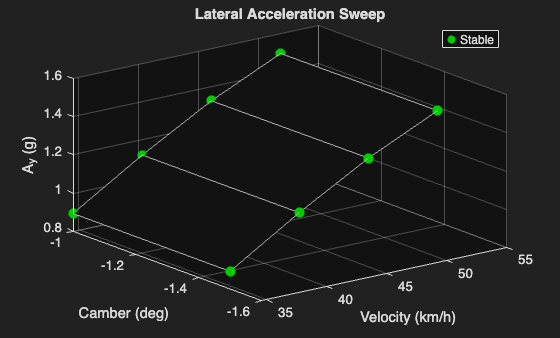

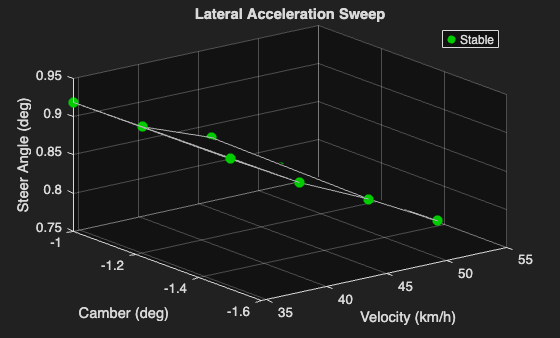

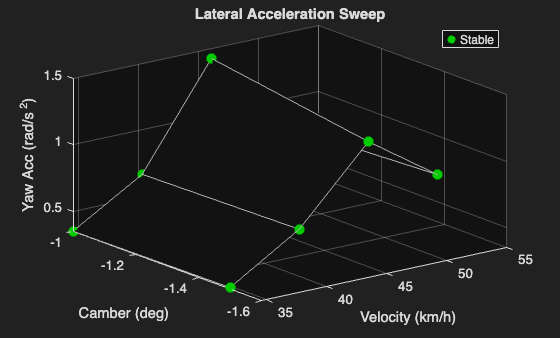

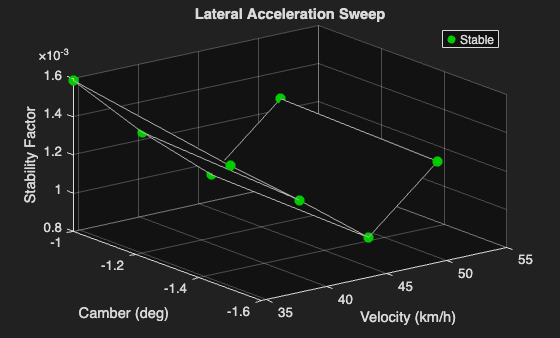

% Clear results figure if it already exists.
if exist('sm_car_sweep_Ay', 'var')
    if isgraphics(sm_car_sweep_Ay, 'figure')
        clf( sm_car_sweep_Ay, 'reset' );
    end
end
if exist('sm_car_sweep_K', 'var')
    if isgraphics(sm_car_sweep_K, 'figure')
        clf( sm_car_sweep_K, 'reset' );
    end
end
if exist('sm_car_sweep_aSteer', 'var')
    if isgraphics(sm_car_sweep_aSteer, 'figure')
        clf( sm_car_sweep_aSteer, 'reset' );
    end
end
if exist('sm_car_sweep_gYaw', 'var')
    if isgraphics(sm_car_sweep_gYaw, 'figure')
        clf( sm_car_sweep_gYaw, 'reset' );
    end
end

% Get results to plot.
maxLatAcc = [simOut.maxAy];
failureModes = [simOut.failureReason];
aSteer = [simOut.aSteerWheel];
gYaw = [simOut.gYaw];
K = [simOut.Ku];

% Reshape and scale data
maxLatAccG = maxLatAcc / 9.81; % Convert to g's from m/s^2
maxAyMesh = reshape(maxLatAccG, length(aCamber), length(vGain)); % create the mesh from simulation output
aSteerMesh = reshape(aSteer, length(aCamber), length(vGain)); % create the mesh from simulation output
gYawMesh = reshape(gYaw, length(aCamber), length(vGain)); % create the mesh from simulation output
KMesh = reshape(K, length(aCamber), length(vGain)); % create the mesh from simulation output

baseVelKmH = max(Maneuver.Trajectory.vx.Value) * 3.6; % Base maneuver speed in km/h from m/s
vActual = vGain .* baseVelKmH;   % 1D vector for axes and mesh/lines
VACTUAL = VGAIN .* baseVelKmH;   % Flattened array for scatter points

% Define Colors and Categories for the Legend
catNames = ["Stable", "Understeer", "Oversteer", "Wheels Lift"];
catColors = [0 0.8 0;    % Green
             0.9 0.9 0;  % Yellow
             1 0 0;      % Red
             0.5 0 0.5]; % Purple


% Create plot figure and make sure it is visible
if ~isscalar(maxAyMesh)
    sm_car_sweep_Ay = figure('Name', 'sm_car_sweep_Ay', 'Visible', 'on', 'WindowStyle', 'normal');
    sm_car_sweep_aSteer = figure('Name', 'sm_car_sweep_aSteer', 'Visible', 'on', 'WindowStyle', 'normal');
    sm_car_sweep_gYaw = figure('Name', 'sm_car_sweep_gYaw', 'Visible', 'on', 'WindowStyle', 'normal');
    sm_car_sweep_K = figure('Name', 'sm_car_sweep_K', 'Visible', 'on', 'WindowStyle', 'normal');

end

% Plot the sweep based on dimensions
if ismatrix(maxAyMesh) && length(vGain)>1 && length(aCamber)>1
    %% 3D MESH PLOT 
    % Plot the base mesh 
    figure(sm_car_sweep_Ay); % ensure the figure is selected

    mesh(vActual, aCamber, maxAyMesh, 'EdgeColor', [0.7 0.7 0.7], 'HandleVisibility', 'off');
    hold on; grid on;
    
    % Overlay colored scatter points for each category
    for iCat = 1:4
        idx = (failureModes(:) == catNames(iCat));
        if any(idx)
            scatter3(VACTUAL(idx), ACAMBER(idx), maxLatAccG(idx), 60, catColors(iCat,:), 'filled', 'DisplayName', catNames(iCat));
        end
    end
    
    title('Lateral Acceleration Sweep');
    xlabel('Velocity (km/h)');
    ylabel('Camber (deg)');
    zlabel('A_{y} (g)');
    legend('Location', 'best');
    hold off;
    
    figure(sm_car_sweep_aSteer); % ensure the figure is selected

    mesh(vActual, aCamber, aSteerMesh, 'EdgeColor', [0.7 0.7 0.7], 'HandleVisibility', 'off');
    hold on; grid on;
    
    % Overlay colored scatter points for each category
    for iCat = 1:4
        idx = (failureModes(:) == catNames(iCat));
        if any(idx)
            scatter3(VACTUAL(idx), ACAMBER(idx), aSteerMesh(idx), 60, catColors(iCat,:), 'filled', 'DisplayName', catNames(iCat));
        end
    end
    
    title('Lateral Acceleration Sweep');
    xlabel('Velocity (km/h)');
    ylabel('Camber (deg)');
    zlabel('Steer Angle (deg)');
    legend('Location', 'best');
    hold off;

    figure(sm_car_sweep_gYaw); % ensure the figure is selected

    mesh(vActual, aCamber, gYawMesh, 'EdgeColor', [0.7 0.7 0.7], 'HandleVisibility', 'off');
    hold on; grid on;
    
    % Overlay colored scatter points for each category
    for iCat = 1:4
        idx = (failureModes(:) == catNames(iCat));
        if any(idx)
            scatter3(VACTUAL(idx), ACAMBER(idx), gYawMesh(idx), 60, catColors(iCat,:), 'filled', 'DisplayName', catNames(iCat));
        end
    end
    
    title('Lateral Acceleration Sweep');
    xlabel('Velocity (km/h)');
    ylabel('Camber (deg)');
    zlabel('Yaw Acc (rad/s ^{2})');
    legend('Location', 'best');
    hold off;
   
    figure(sm_car_sweep_K); % ensure the figure is selected

    mesh(vActual, aCamber, KMesh, 'EdgeColor', [0.7 0.7 0.7], 'HandleVisibility', 'off');
    hold on; grid on;
    
    % Overlay colored scatter points for each category
    for iCat = 1:4
        idx = (failureModes(:) == catNames(iCat));
        if any(idx)
            scatter3(VACTUAL(idx), ACAMBER(idx), K(idx), 60, catColors(iCat,:), 'filled', 'DisplayName', catNames(iCat));
        end
    end
    
    title('Lateral Acceleration Sweep');
    xlabel('Velocity (km/h)');
    ylabel('Camber (deg)');
    zlabel('Stability Factor');
    legend('Location', 'best');
    hold off;
    
else 
    if length(vGain) > length(aCamber)
        % 2D PLOT W.R.T VELOCITY 
        % Draw the connecting line
        figure(sm_car_sweep_Ay); % ensure the figure is selected
        
        plot(vActual, maxAyMesh, 'b-', 'LineWidth', 1.5, 'HandleVisibility', 'off');
        hold on; grid on;
        
        % Overlay colored scatter points
        for iCat = 1:4
            idx = (failureModes(:) == catNames(iCat));
            if any(idx)
                scatter(VACTUAL(idx), maxLatAccG(idx), 70, catColors(iCat,:), 'filled', 'DisplayName', catNames(iCat));
            end
        end
        
        title('Lateral Acceleration Sweep w.r.t. Velocity');
        if isscalar(aCamber)
            subtitle(sprintf('Camber = %.2f deg', aCamber));
        end
        xlabel('Velocity (km/h)');
        ylabel('A_{y} (g)');
        legend('Location', 'best');
        hold off;

        figure(sm_car_sweep_aSteer); % ensure the figure is selected
        
        plot(vActual, aSteerMesh, 'b-', 'LineWidth', 1.5, 'HandleVisibility', 'off');
        hold on; grid on;
        
        % Overlay colored scatter points
        for iCat = 1:4
            idx = (failureModes(:) == catNames(iCat));
            if any(idx)
                scatter(VACTUAL(idx), aSteerMesh(idx), 70, catColors(iCat,:), 'filled', 'DisplayName', catNames(iCat));
            end
        end
        
        title('Lateral Acceleration Sweep w.r.t. Velocity');
        if isscalar(aCamber)
            subtitle(sprintf('Camber = %.2f deg', aCamber));
        end
        xlabel('Velocity (km/h)');
        ylabel('Steer Angle (deg)');
        legend('Location', 'best');
        hold off;
         
        figure(sm_car_sweep_gYaw); % ensure the figure is selected
        
        plot(vActual, gYawMesh, 'b-', 'LineWidth', 1.5, 'HandleVisibility', 'off');
        hold on; grid on;
        
        % Overlay colored scatter points
        for iCat = 1:4
            idx = (failureModes(:) == catNames(iCat));
            if any(idx)
                scatter(VACTUAL(idx), gYawMesh(idx), 70, catColors(iCat,:), 'filled', 'DisplayName', catNames(iCat));
            end
        end
        
        title('Lateral Acceleration Sweep w.r.t. Velocity');
        if isscalar(aCamber)
            subtitle(sprintf('Camber = %.2f deg', aCamber));
        end
        xlabel('Velocity (km/h)');
        ylabel('Yaw Acc (rad/s^{2})');
        legend('Location', 'best');
        hold off;
        
        figure(sm_car_sweep_K); % ensure the figure is selected
        
        plot(vActual, KMesh, 'b-', 'LineWidth', 1.5, 'HandleVisibility', 'off');
        hold on; grid on;
        
        % Overlay colored scatter points
        for iCat = 1:4
            idx = (failureModes(:) == catNames(iCat));
            if any(idx)
                scatter(VACTUAL(idx), KMesh(idx), 70, catColors(iCat,:), 'filled', 'DisplayName', catNames(iCat));
            end
        end
        
        title('Lateral Acceleration Sweep w.r.t. Velocity');
        if isscalar(aCamber)
            subtitle(sprintf('Camber = %.2f deg', aCamber));
        end
        xlabel('Velocity (km/h)');
        ylabel('Stability Factor');
        legend('Location', 'best');
        hold off;
        
    elseif length(vGain) < length(aCamber)
        % 2D PLOT W.R.T CAMBER
        % Draw the connecting line
        figure(sm_car_sweep_Ay); % ensure the figure is selected

        plot(aCamber, maxAyMesh, 'b-', 'LineWidth', 1.5, 'HandleVisibility', 'off');
        hold on; grid on;
        
        % Overlay colored scatter points
        for iCat = 1:4
            idx = (failureModes(:) == catNames(iCat));
            if any(idx)
                scatter(ACAMBER(idx), maxLatAccG(idx), 70, catColors(iCat,:), 'filled', 'DisplayName', catNames(iCat));
            end
        end
        
        title('Lateral Acceleration Sweep w.r.t. Camber');
        if isscalar(vGain)
            subtitle(sprintf('Velocity = %.2f km/h', vActual)); 
        end
        xlabel('Camber (deg)');
        ylabel('A_{y} (g)');
        legend('Location', 'best');
        hold off;

        figure(sm_car_sweep_aSteer); % ensure the figure is selected

        plot(aCamber, aSteerMesh, 'b-', 'LineWidth', 1.5, 'HandleVisibility', 'off');
        hold on; grid on;
        
        % Overlay colored scatter points
        for iCat = 1:4
            idx = (failureModes(:) == catNames(iCat));
            if any(idx)
                scatter(ACAMBER(idx), aSteerMesh(idx), 70, catColors(iCat,:), 'filled', 'DisplayName', catNames(iCat));
            end
        end
        
        title('Lateral Acceleration Sweep w.r.t. Camber');
        if isscalar(vGain)
            subtitle(sprintf('Velocity = %.2f km/h', vActual)); 
        end
        xlabel('Camber (deg)');
        ylabel('Steer Angle (deg)');
        legend('Location', 'best');
        hold off;
        
        figure(sm_car_sweep_gYaw); % ensure the figure is selected

        plot(aCamber, gYawMesh, 'b-', 'LineWidth', 1.5, 'HandleVisibility', 'off');
        hold on; grid on;
        
        % Overlay colored scatter points
        for iCat = 1:4
            idx = (failureModes(:) == catNames(iCat));
            if any(idx)
                scatter(ACAMBER(idx), gYawMesh(idx), 70, catColors(iCat,:), 'filled', 'DisplayName', catNames(iCat));
            end
        end
        
        title('Lateral Acceleration Sweep w.r.t. Camber');
        if isscalar(vGain)
            subtitle(sprintf('Velocity = %.2f km/h', vActual)); 
        end
        xlabel('Camber (deg)');
        ylabel('Yaw Acc (rad/s^{2})');
        legend('Location', 'best');
        hold off;
        
        figure(sm_car_sweep_K); % ensure the figure is selected

        plot(aCamber, KMesh, 'b-', 'LineWidth', 1.5, 'HandleVisibility', 'off');
        hold on; grid on;
        
        % Overlay colored scatter points
        for iCat = 1:4
            idx = (failureModes(:) == catNames(iCat));
            if any(idx)
                scatter(ACAMBER(idx), KMesh(idx), 70, catColors(iCat,:), 'filled', 'DisplayName', catNames(iCat));
            end
        end
        
        title('Lateral Acceleration Sweep w.r.t. Camber');
        if isscalar(vGain)
            subtitle(sprintf('Velocity = %.2f km/h', vActual)); 
        end
        xlabel('Camber (deg)');
        ylabel('Stabiltiy Factor');
        legend('Location', 'best');
        hold off;
        
        
    else 
        % Display in the command window the values if there is only 1 sim
        disp(['Max lateral for ', num2str(aCamber), ' deg camber and ', num2str(vActual), ' km/h is: ', num2str(maxAyMesh), ' g']);
    end
end


shg; % ensure the figure is shown on top 

% Switch the Mechanics Explorer back on
set_param(modelName,'SimMechanicsOpenEditorOnUpdate','on');
